# TCLab On/Off Control

**Objective:** Generate data from an On/Off controller and determine the parameters of a 2nd order underdamped model that best fits the response.

On/off control is used in most cooling and heating applications where the actuator can only be On or Off. Run the temperature control lab with On/Off control for 4 minutes to reach a setpoint of $40^\circ\text{C}$.

## 4 Minutes of On/Off Control

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
filename = "onoff.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    Q1_ = A(:,3);
    disp('TCLab Data read from file')

    subplot(2,1,1)
    plot(tm_, T1_, 'r.', 'DisplayName','T1')
    hold on
    plot([0,tm_(end)],[40,40], 'DisplayName', 'setpoint')
    legend("Location","best")
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, Q1_, 'r-', 'DisplayName', 'Q1')
    ylabel('Heater Setting')
    xlabel('Time (s)')
    
catch % if file can not be found, simulate
    try 
        n = 240;
        tm_ = zeros(n, 1);
        T1_ = ones(n, 1) * 23.0;
        Q1_ = zeros(n, 1);
        
        lab = tclab;
        tic;
        figure()
        for i =1:240
            pause(1)
            tm_(i) = toc;
            T1_(i) = lab.T1;
            if T1_(i) < 40.0
                Q1_(i) = 100;
            else
                Q1_(i) = 0;
            end
            lab.Q1(Q1_(i));
            
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName','T1')
            legend("Location","best")
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName', 'Q1')
            ylabel('Heater Setting')
            xlabel('Time (s)')
        end    
        A = [tm_, T1_, Q1_]
        writematrix(A, absolute_path, 'Delimiter', ',')
    catch
        lab.off
        clear lab
    end
    
end

Use a graphical method to fit to the closed-loop response by finding $K_p$, $\zeta$, and $\tau_s$. Dead-time $\theta_p$ is not needed for this model.


$$\tau_s^2 \frac{d^2T_1}{dt^2} + 2 \zeta \tau_s \frac{dT_1}{dt} + T_1 = K_p \, Q_1$$


Follow the steps to obtain a graphical approximation of a step response of the underdamped (oscillating) second order system. An underdamped system implies that $0 \ge \zeta > 1$.

- Find $\Delta T_1$ from step response.

- Find $\Delta T_{SP}$ as the input to the step response.

- Calculate $K_p=\frac{\Delta T_1}{\Delta T_{SP}}$.

- Calculate damping factor $\zeta$ from overshoot OS or decay ratio DR.

- Calculate $\tau_s
$ from equations for rise time $t_r$, peak time $t_p$, or period P.

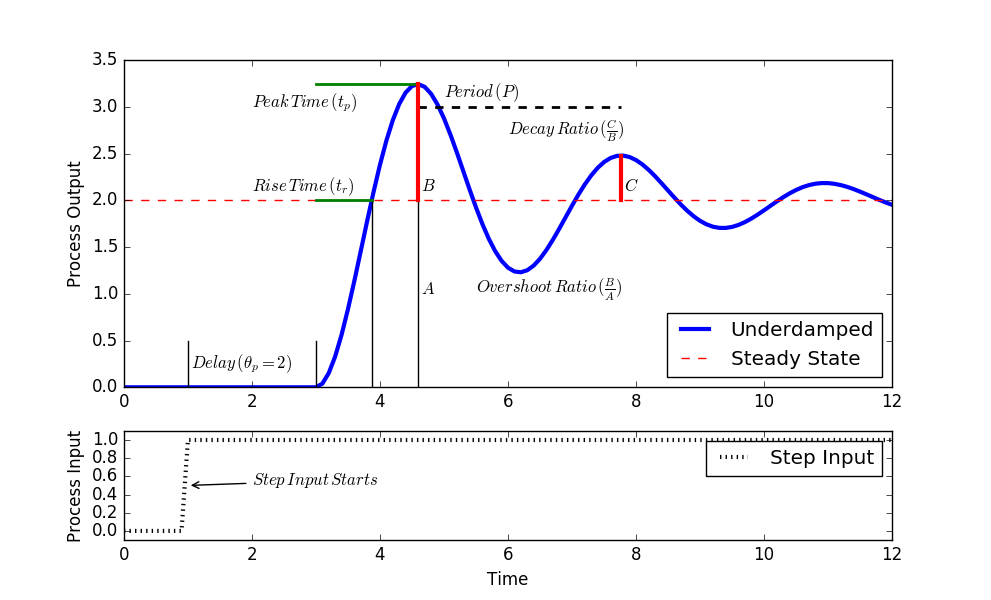

### Helpful Correlations

The graphical metrics are dependent on $\zeta$ and $\tau_s$ with the following correlations. For example, it is easiest to use equations for overshoot and decay ratio to calculate $\zeta$. The value for $\tau_s$ can then be calculated from rise time $t_r$, peak time $t_p$, or period $P$.

- Rise time $t_r$: amount of time to first cross the steady state level (after accounting for dead time).


$$t_r = \frac{\tau_s}{\sqrt{1-\zeta^2}}\left( \pi - cos^{-1} \zeta \right)$$


- Peak time $t_p$: amount of time to reach the first peak (after accounting for dead time).


$$t_p = \frac{\pi \tau_s}{\sqrt{1-\zeta^2}} \quad \quad \tau_s = \frac{\sqrt{1-\zeta^2}}{\pi}t_p$$


- Overshoot ratio $OS$: amount that first oscillation surpasses the steady state level relative to the steady state change


$$OS = \exp\left({-\frac{\pi \zeta}{\sqrt{1-\zeta^2}}}\right) \quad \quad \zeta = \sqrt{\frac{\left(\ln(OS)\right)^2}{\pi^2 + \left(\ln(OS)\right)^2}}$$


- Decay ratio $DR$: fractional size of successive peaks


$$DR = OS^2 = \exp\left({-\frac{2 \pi \zeta}{\sqrt{1-\zeta^2}}}\right)$$


- Period $P$: the length of time for an oscillation from peak to peak


$$P = \frac{2 \pi \tau_s}{\sqrt{1-\zeta^2}} \quad \quad \tau_s = \frac{\sqrt{1-\zeta^2}}{2 \pi}P$$


Another method to obtain the parameters is with an optimization method such as minimizing a sum of squared errors differences between measured and predicted values.

### Assignment

Add the underdamped ($0 \ge \zeta > 1$) analytic solution to data plot to compare the graphical fit to the data. See Second Order Systems for additional information on analytic solutions.

viewSolution(false)

 
$$T'_1(t) = K_p \Delta T_{SP} \left( 1-e^{-\zeta\,t/\tau_s} \left[ \cos\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) + \frac{\zeta}{\sqrt{1-\zeta^2}} \sin\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) \right] \right)$$


% graphic fit
Delta_SP =  
Delta_T1 =  
OS =  
tp =  
Kp =  
zeta =  
taus =  
disp('Kp: ' + string(Kp))
disp('zeta: ' + string(zeta))
disp('taus: ' + string(taus))

%analytic solution
T1 =  

% plot
figure()
subplot(2,1,1)
plot(tm_, T1_, 'r.', 'DisplayName','TCLab')
hold on
plot(tm_, T1, 'r-', 'DisplayName','SOPDT')
hold off
legend("Location","best")
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_, Q1_, 'r-', 'DisplayName', 'Q1')
ylabel('Heater Setting')
xlabel('Time (s)')

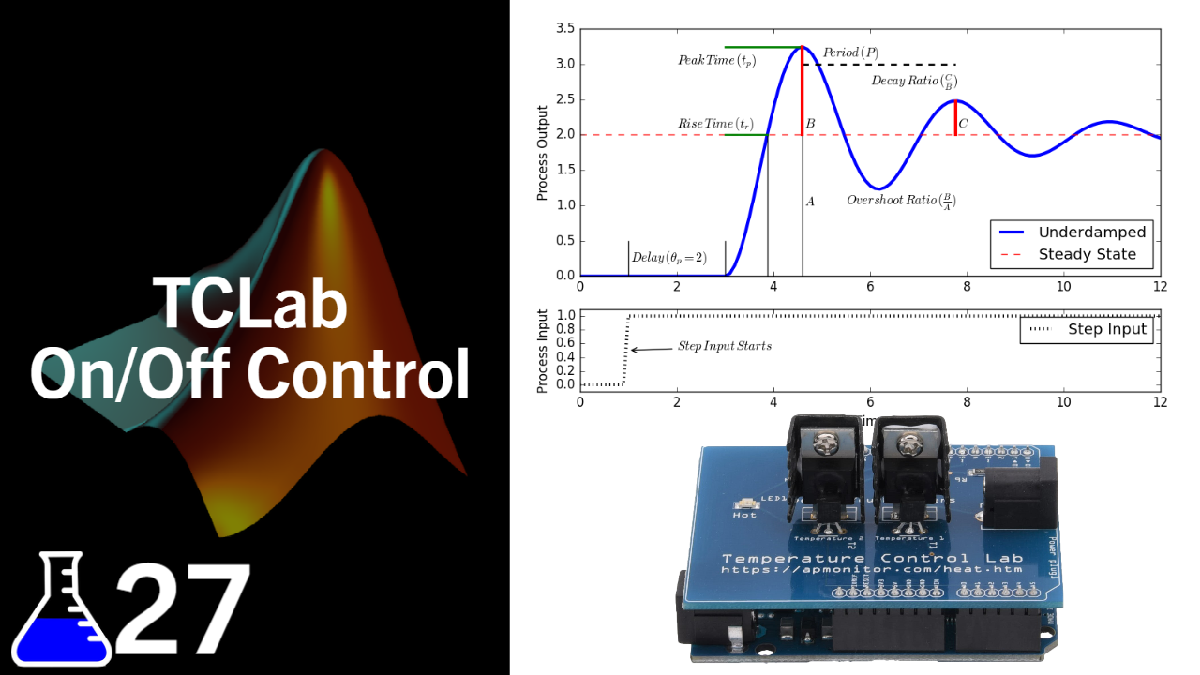

### [View Solution](https://youtu.be/k5bvLeyRjQM)

function viewSolution(view)
if view
	disp("T0 = T1_(1);" + newline + ...
	     "a = sqrt(1-zeta^2);" + newline + ...
	     "b = tm_/taus;" + newline + ...
	     "c = cos(a.*b);" + newline + ...
	     "d = (zeta/a)*sin(a*b);" + newline + ...
	     "T1 = Kp * Delta_SP * (1-exp(-zeta * b)*(c+d)) + T0")
end
end